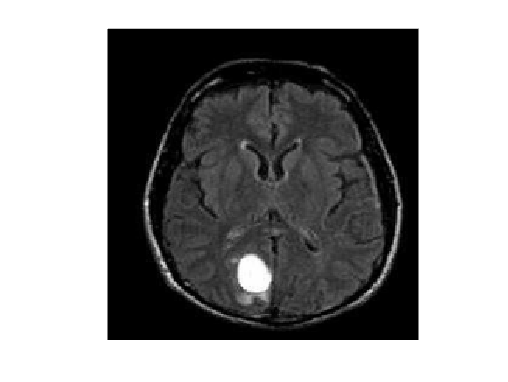

mri = imread("7.png");
mri = imresize(mri,[200,200]);
% Converting rgb image to grayscale image
mri = im2gray(mri);
imshow(mri)

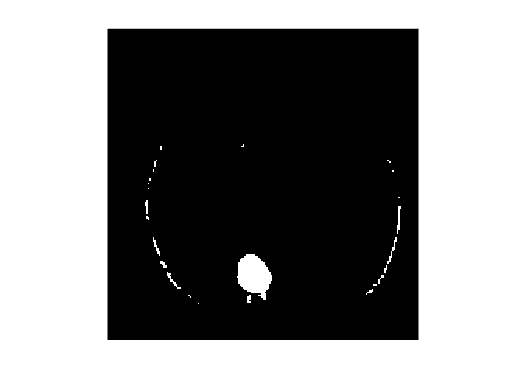

%  Converting grayscale image to binary image
mri = imbinarize(mri,0.6);
imshow(mri)

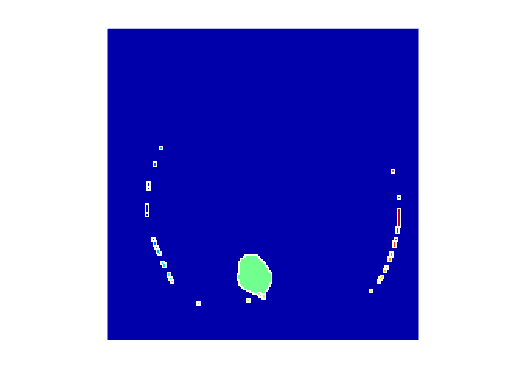


% Sobel filter in horizontal direction; edge-detection filter that highlights horizontal edges in an image.
filter_x = fspecial('sobel');
% Similarly in vertical direction
filter_y = filter_x';
mriy = imfilter(double(mri), filter_y, 'replicate');
mrix = imfilter(double(mri), filter_x, 'replicate');
% Gradient magnitude
mri_gradmag = sqrt(mrix.^2 + mriy.^2);

% Watershed
mri_ws = watershed(mri_gradmag);
mri_rgb_ws = label2rgb(mri_ws);
imshow(mri_rgb_ws)

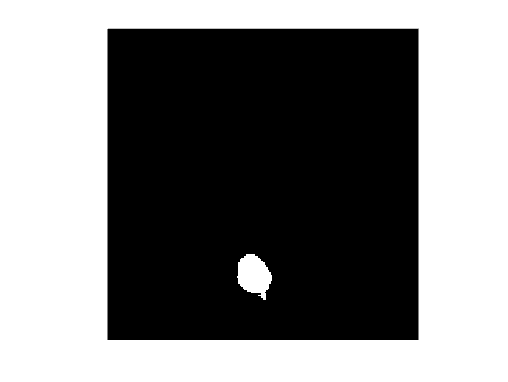


% morphological operations
se = strel('disk', 5);
mrio = imopen(mri, se);
mriobr = imreconstruct(mrio, mri);
imshow(mriobr)

mriobrd = imdilate(mriobr, se);
mriobrcbr = imreconstruct(imcomplement(mriobrd), imcomplement(mriobr));
mriobrcbr = imcomplement(mriobrcbr);

% identifies the potential tumor regions
mri2 = mri;
fgm = imregionalmax(mriobrcbr);
mri2(fgm) = 255;
se2 = strel(ones(5,5));
fgm2 = imclose(fgm, se2);
fgm3 = imerode(fgm2, se2);
fgm4 = bwareaopen(fgm3, 20);

% Measure the size of the tumor
cc = bwconncomp(mriobrcbr);
props = regionprops(cc, 'Area');

% Calculate the physical size of a pixel in square centimeters (replace with actual values)
pixel_width_cm = 0.0508;  % Width of a pixel in centimeters
pixel_height_cm = 0.0508; % Height of a pixel in centimeters

% Calculate and display the size of the tumor in pixels
tumor_size_pixels = sum([props.Area]);
% fprintf('Tumor size in pixels: %d\n', tumor_size_pixels);

% Calculate the tumor size in square centimeters
tumor_size_cm2 = tumor_size_pixels * pixel_width_cm * pixel_height_cm;
fprintf('Tumor size in square centimeters: %f cm^2\n', tumor_size_cm2);

Tumor size in square centimeters: 1.140643 cm^2


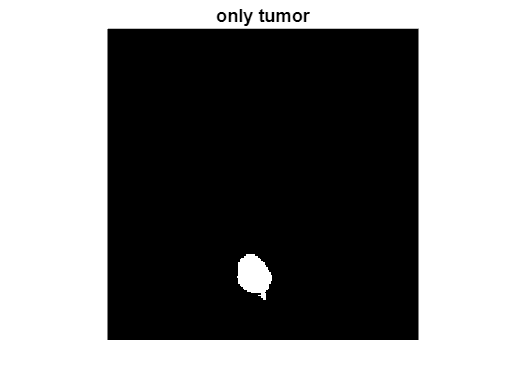


% Categorize the tumor based on the size
if tumor_size_cm2 == 0
    tumor_category = 'No tumor';
elseif tumor_size_cm2 <= 2.37
    tumor_category = 'Benign';
    imshow(mriobrcbr), title('only tumor')
else
    tumor_category = 'Malignant';
    imshow(mriobrcbr), title('only tumor')
end


fprintf('Tumor category: %s\n', tumor_category);

Tumor category: Benign
